load arrhythmia X Y Description VarNames
binaryResponse = categorical(Y);
binaryResponse = mergecats(binaryResponse,{'2','3','4','5','6','7','8','9','10','11','12','13','14','15','16'});
binaryResponse = renamecats(binaryResponse,["1","2"], ["No Arrhythmia" "Arrhythmia"]);
classificationLearner

impValues = predictorImportance(trainedModel.ClassificationTree)

impValues =          0         0    0.0005         0    0.0010         0         0         0         0         0         0         0    0.0004         0    0.0036         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0003         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


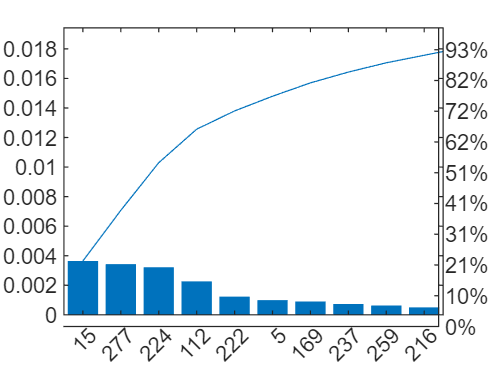

pareto(impValues,1:length(impValues),0.9)

ddkas

f